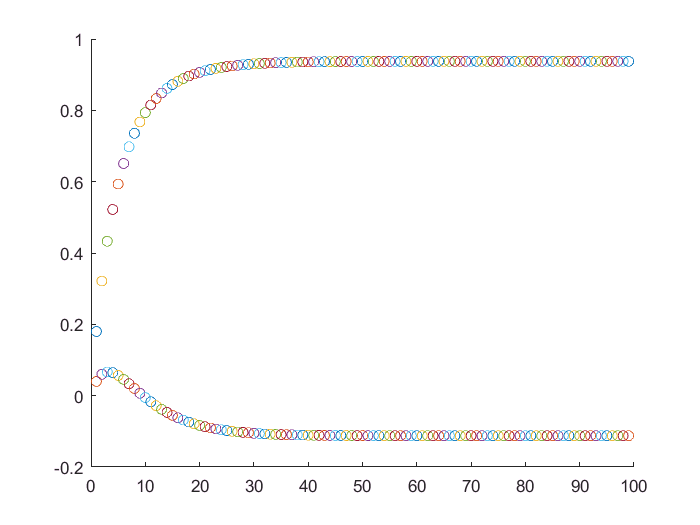

es = input('Enter Eigen Spread value:');
a = (es-1)/(es+1);
R=[1 a;a 1];
p=[0.9 0.2]';
step= input('Enter Step size:');
% Initialize the weights
w_init=[0 ; 0];
j=0;

% Steepest Descend Algorithm with optimum step size computation on each iteration
k=1;
while (100-k~=0)
    hold on
    w_new=w_init + step*(p-R*w_init);
    j=1- 2*w_new(1,1)*p(1,1) - 2*w_new(2,1)*p(2,1) + w_new(1,1)*w_new(1,1)*R(1,1) + 2*w_new(1,1)*w_new(2,1)*R(1,2) + w_new(2,1)*w_new(2,1)*R(1,1);
    % plot(k,j,'-o');
    plot(k,w_new,'o');
    w_init=w_new;
    k=k+1;    
end
hold off